# Structural Covariance and Connectivity in Maltreated Children

% The data and codes are downloaded from https://github.com/laplcebeltrami/maltreated
% If you are using the codes or data, please provide references below.
%
% The structural covariance data is explained in 
% [1] Chung, M.K., Hanson, J.L., Ye, J., Davidson, R.J. Pollak, S.D. 2015 
% Persistent homology in sparse regression and its application to brain morphometry. 
% IEEE Transactions on Medical Imaging, 34:1928-1939 
% http://pages.stat.wisc.edu/~mchung/papers/chung.2015.TMI.pdf
%
% [2] Chung, M.K., Hanson, J.L., Lee, H., Adluru, N., Alexander1, A.L., Davidson, A.L., Pollak, S.D. 2013. 
% Persistent homological sparse network approach to detecting white matter abnormality in maltreated children: 
% MRI and DTI multimodal study, 16th International Conference on Medical Image Computing and Computer Assisted 
% Intervention (MICCAI). Lecture Notes in Computer Science (LNCS) 8149:300-307 
% https://pages.stat.wisc.edu/~mchung/papers/chung.2013.MICCAI.pdf
%
%
% % (C) 2013- Moo K. Chung mkchung@wisc.edu
% Universtiy of Wisconsin-Madison

%Subject ID
id =[ 
     2     0    13     0
     4     0    11     0
     5     0    13     1
    13     1    11     1
    19     1    13     0
    20     1     9     1
    22     1    12     0
    24     1    13     0
    26     0    10     0
    27     0    12     0
    30     0    12     0
    31     1    12     1
    32     1     9     0
    36     0    11     1
    37     0    10     0
    38     0    13     0
    39     0    14     0
    41     0    11     1
    42     0     9     0
    43     0    14     1
    44     1    14     1
    46     0    10     1
    47     0    13     1
    48     0    13     1
    49     0    13     1
    52     0    10     1
    64     0    12     1
    82     1     9     1
    93     1    10     0
    96     0     9     0
    97     1    13     1
    98     1    12     0
   102     1    10     0
   103     0    10     0
   106     1    12     0
   109     1     9     0
   110     1    14     0
   112     1     9     1
   113     1    11     0
   119     0     9     0
   121     0     9     1
   131     0    12     1
   132     1    10     0
   133     0    14     1
   134     0    12     1
   135     0    14     1
   136     0    11     1
   140     0    12     1
   149     1    13     1
   150     1    11     0
   153     0    12     0
   158     1    13     1
   159     1    10     1
   162     0    11     1];

group=id(:,2); % control 0, maltreted (post instutitualized) 1 
nGroup_pi=sum(group) %maltreated

nGroup_pi = 23

nGroup_co=sum(~group) %controls

nGroup_co = 31

gender=id(:,4); % female 0 male 1
age=id(:,3); %age of subjects in years

## Section 1. DTI connectivity from white matter fiber tractography 

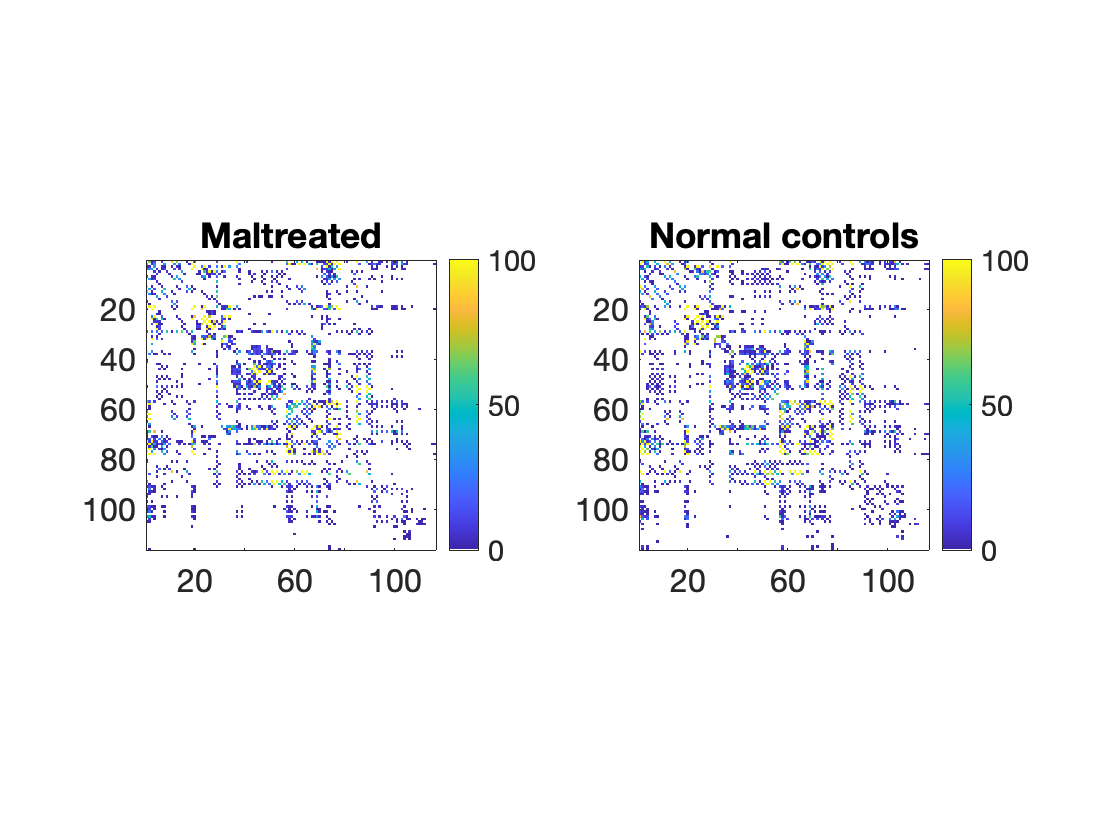

% The data and codes are downloaded from https://github.com/laplcebeltrami/maltreated
% If you are using the codes or data, please provide references below.
%
% The structural connectivity data is explained in
%
% Chung, M.K., Hanson, J.L., Adluru, Aleander, A.L., Davidson, R.J., Pollak, S.D. 2017 
% Integrative structural brain network analysis in diffusion tensor imaging, 
% Brain Connectivity 7:331-346
% https://pages.stat.wisc.edu/~mchung/papers/chung.2017.connectivity.pdf
%
% % (C) 2017- Moo K. Chung mkchung@wisc.edu
% Universtiy of Wisconsin-Madison

load connectivity-DTIcounts.mat  %count the numbrer of fiber tracts between AAL parcellations

%Connectivity in each group
con_pi = connectivity(:,:,logical(group));
con_pim= mean(con_pi, 3);
con_co = connectivity(:,:,~logical(group));
con_com= mean(con_co, 3);

custom_colormap = [1, 1, 1; colormap]; %make 0 entry white

figure; subplot(1,2,1); imagesc(con_pim); axis square; colorbar
title('Maltreated'); figure_bigger(16); colormap(custom_colormap); clim([0 100])

subplot(1,2,2)
imagesc(con_com); colorbar; axis square; colorbar
title('Normal controls'); figure_bigger(16); colormap(custom_colormap); clim([0 100])

### Betti plot visualization of DTI-connectivity matrices

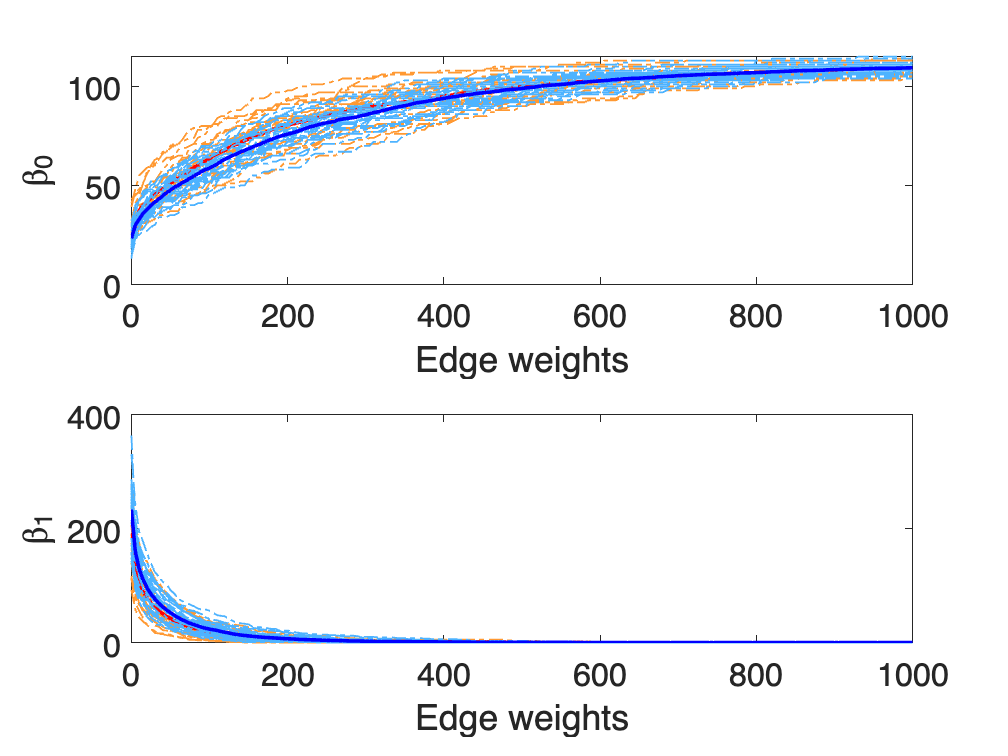

thresholds=[0:5:1000]; %you can change the range
PH_graph_betti_display(con_pi, con_co,thresholds) %con_pi read, con_co is blue

### Topological inference on DTI-connectivity matrices

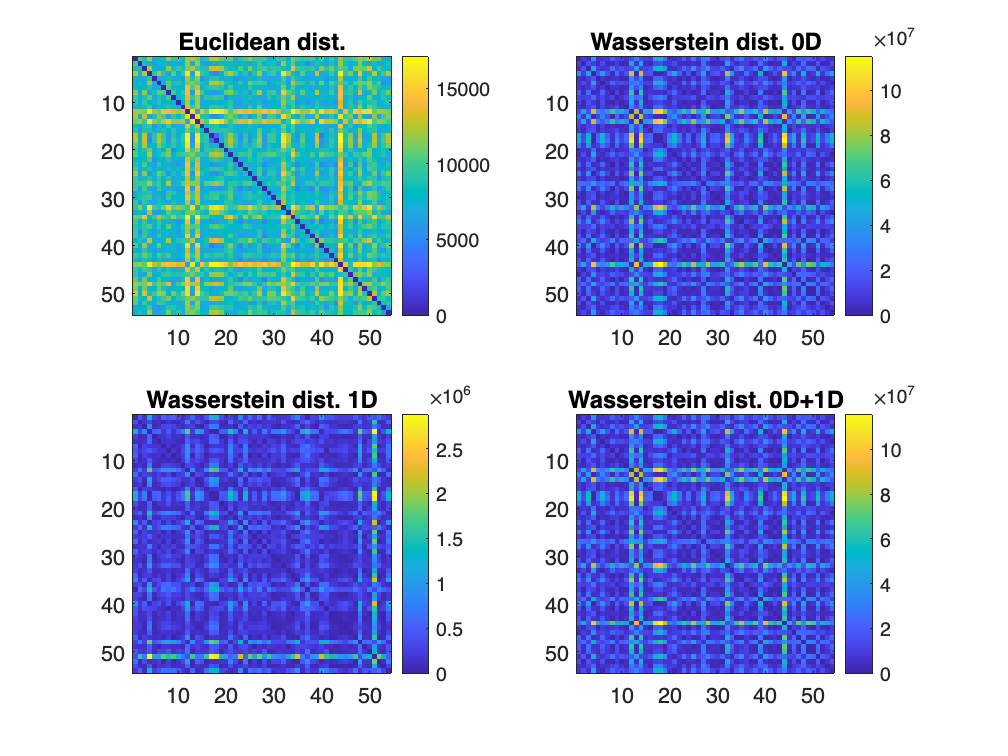

con_pi = con_pi + normrnd(0,0.00001,116,116,nGroup_pi);
con_co = con_co + normrnd(0,0.00001,116,116,nGroup_co);
lossMtx = WS_pdist2(con_pi,con_co);
WS_pdist2_display(con_pi,con_co);

% p-value computation using the raio statistic (between-distance/within-distance)
%Here we show example of using the combined distance. For different
%distances,use lossMtx.D0 or lossMtx.D1, lossMtx.D01 = lossMtx.D0 + lossMtx.D1.

observed = WS_ratio(lossMtx.D0, nGroup_pi, nGroup_co) 

observed = 0.9943

nTrans = 1000000; %Total number of transpositions
permNo = 1000; %Total number of intermixed permutations. This is needed to introduce randomness.

[transStat, ~] = WS_transpositions(lossMtx.D0, nGroup_pi, nGroup_co, nTrans, permNo); 
transPval = online_pvalues(transStat', observed);
pval = transPval(end)

pval = 0.5654

observed = WS_ratio(lossMtx.D1, nGroup_pi, nGroup_co) 

observed = 1.0135

[transStat, ~] = WS_transpositions(lossMtx.D1, nGroup_pi, nGroup_co, nTrans, permNo); 
transPval = online_pvalues(transStat', observed);
pval = transPval(end)

pval = 0.3299

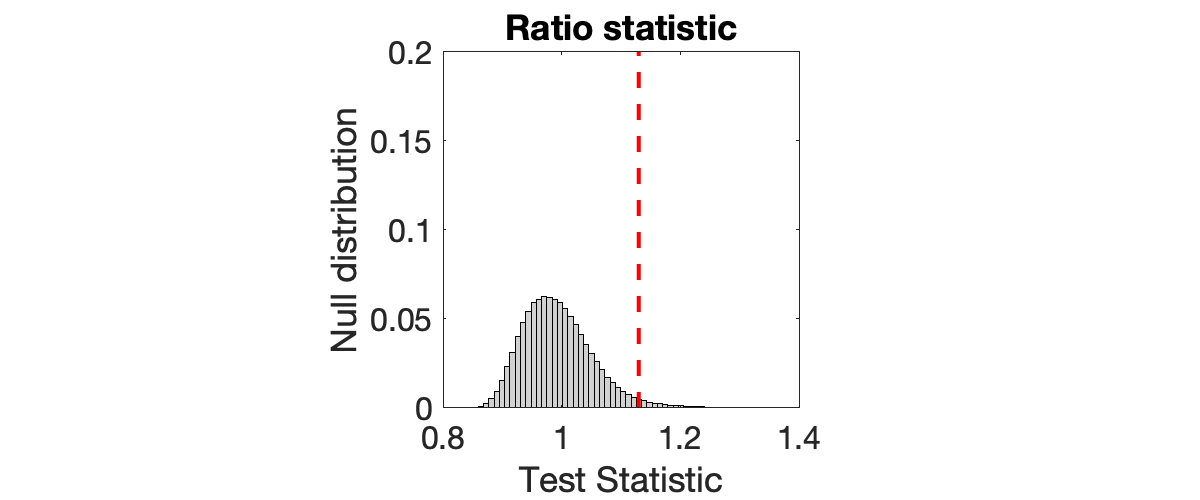


figure; plot_distribution(transStat, 100, 1.13); title('Ratio statistic'); xlim([0.8 1.4]); ylim([0 0.2]); axis square




observed = WS_ratio(lossMtx.D01, nGroup_pi, nGroup_co) 

observed = 0.9947

[transStat, ~] = WS_transpositions(lossMtx.D01, nGroup_pi, nGroup_co, nTrans, permNo); 
transPval = online_pvalues(transStat', observed);
pval = transPval(end)

pval = 0.5659

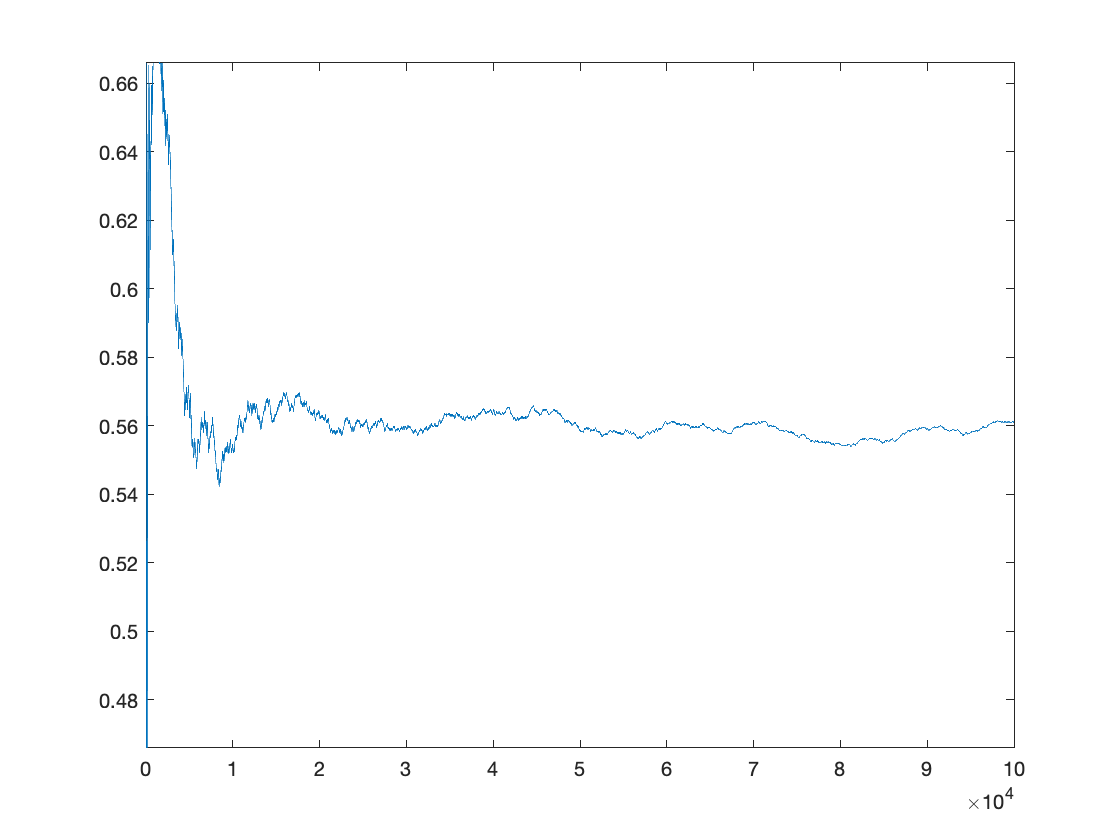

figure; plot(transPval(1:100000)); ylim([pval-0.1 pval+0.1])

## Section 2. Structural Covariance Networks from FA and Jacobian determinants

% This script updates the codes originally given in
%
% The files are downloaded from http://brainimaging.waisman.wisc.edu/~chung/barcodes
% The manual for the codes below is given in the above weblink. 

% The structural covariance data is explained in 
% [1] Chung, M.K., Hanson, J.L., Ye, J., Davidson, R.J. Pollak, S.D. 2015 
% Persistent homology in sparse regression and its application to brain morphometry. 
% IEEE Transactions on Medical Imaging, 34:1928-1939 
% http://pages.stat.wisc.edu/~mchung/papers/chung.2015.TMI.pdf
%
% [2] Chung, M.K., Hanson, J.L., Lee, H., Adluru, N., Alexander1, A.L., Davidson, A.L., Pollak, S.D. 2013. 
% Persistent homological sparse network approach to detecting white matter abnormality in maltreated children: 
% MRI and DTI multimodal study, 16th International Conference on Medical Image Computing and Computer Assisted 
% Intervention (MICCAI). Lecture Notes in Computer Science (LNCS) 8149:300-307 
% https://pages.stat.wisc.edu/~mchung/papers/chung.2013.MICCAI.pdf

% (C) 2013 Moo K. Chung mkchung@wisc.edu
% Universtiy of Wisconsin-Madison


% DATA

load jacobian.mat

% jacobian.mat file contains 
% jacobian  :Jacobian determinant of deforming a template to 54 individual 
%            surfaces. It is sampled at 18881 mesh vertices along the white matter
%            surface.
% surf      :White matter surface template saved as a structured array of
%            size
%                   faces: [37910×3 double]
%                vertices: [18881×3 double].
% nodes:    :548 node uniformly subsampled from 18881 mesh vertices. This
%            is used for smaller networks.
% nodes1856 :1856 node positions uniformly subsampled from 18881 mesh vertices
% group     :control 0, post instutitualized (PI) 1
% gender    :female 0, male 1
% FA        :54 (subjects) x 18881 mesh vertices containing Fractional Anisotropy (FA)


ind=mesh_commonvertex(surf, nodes); 
%surfJJ= jacobian(:,ind); %Jacobian determinant
surfJJ = FA(:,ind); %FA value

% 18881 nodes are too large to handle for computation intensive resampling
% techniques. Thus, we subsample the Jacobian determiannt to 548 nodes
% using mesh_commonvertex.m
% For the results on 1856 nodes, replace "nodes" with "nodes1856".


% surfJJ is 54 (subjects) x 548 (nodes) matrix containing Jacobian determinant. 

X=surfJJ(find(group),:); %X is size 23x548
corr_pi= corrcoef(X);
% corr_pi : correlation matrix of PI

X=surfJJ(find(~group),:);
corr_co= corrcoef(X);
% corr_co: correlation matrix of control



### Visualizing structural covaraiance networks

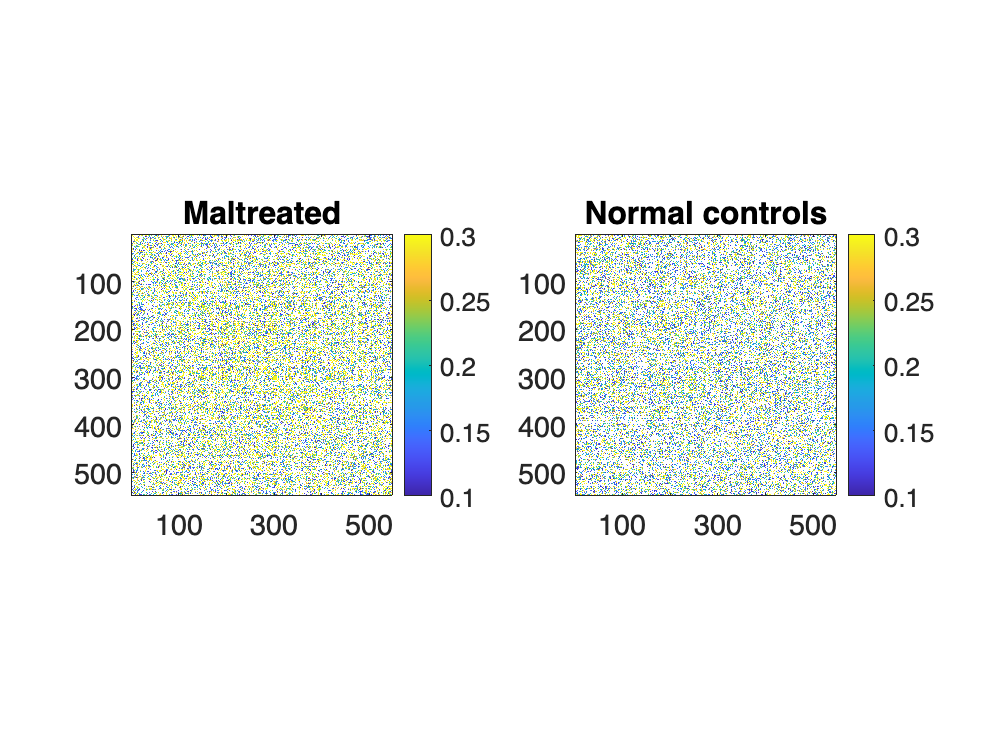

% 3. BETTI PLOTS
%The Betti plots are introduced in Chung, M.K., Hanson, J.L., Ye, J., Davidson, R.J. Pollak, 
%S.D. 2015 Persistent homology in sparse regression and its application to brain morphometry. 
%IEEE Transactions on Medical Imaging, 34:1928-1939


% Constructing network filtration on 1-correlation. 
% number of nodes
custom_colormap = [1, 1, 1; colormap];

figure; subplot(1,2,1); imagesc(corr_pi); axis square; colorbar
title('Maltreated'); figure_bigger(16); colormap(custom_colormap); clim([0.1 0.3])

subplot(1,2,2)
imagesc(corr_co); colorbar; axis square; colorbar
title('Normal controls'); figure_bigger(16); colormap(custom_colormap); clim([0.1 0.3])

### Jackknife resampling of  structural covaraiance networks

%The Jackknife resampling is explained in 
% 
% Chung, M.K., Hanson, J.L., Ye, J., Davidson, R.J. Pollak, S.D. 2015 
% Persistent homology in sparse regression and its application to brain morphometry. 
% IEEE Transactions on Medical Imaging, 34:1928-1939 
% http://pages.stat.wisc.edu/~mchung/papers/chung.2015.TMI.pdf

%controls
m = 31; 
%Jackknife resmplaed correlation matrices
MSTco=zeros(548,548,m); %controls
X=surfJJ(find(~group),:); 
for i=1:m
    Xi= X; 
    Xi(i,:)=[]; %i-th subject removed
    corr_co= corrcoef(Xi);
    MSTco(:,:,i) = corr_co;
end;

%maltreated
n =  23;
MSTpi=zeros(548,548,n);
Y=surfJJ(find(group),:); 
for j=1:n
    Yi= Y; 
    Yi(j,:)=[]; %i-th subject removed
    corr_pi= corrcoef(Yi);
    MSTpi(:,:,j) = corr_pi; 
end;


### Betti curves of structural covaraiance networks

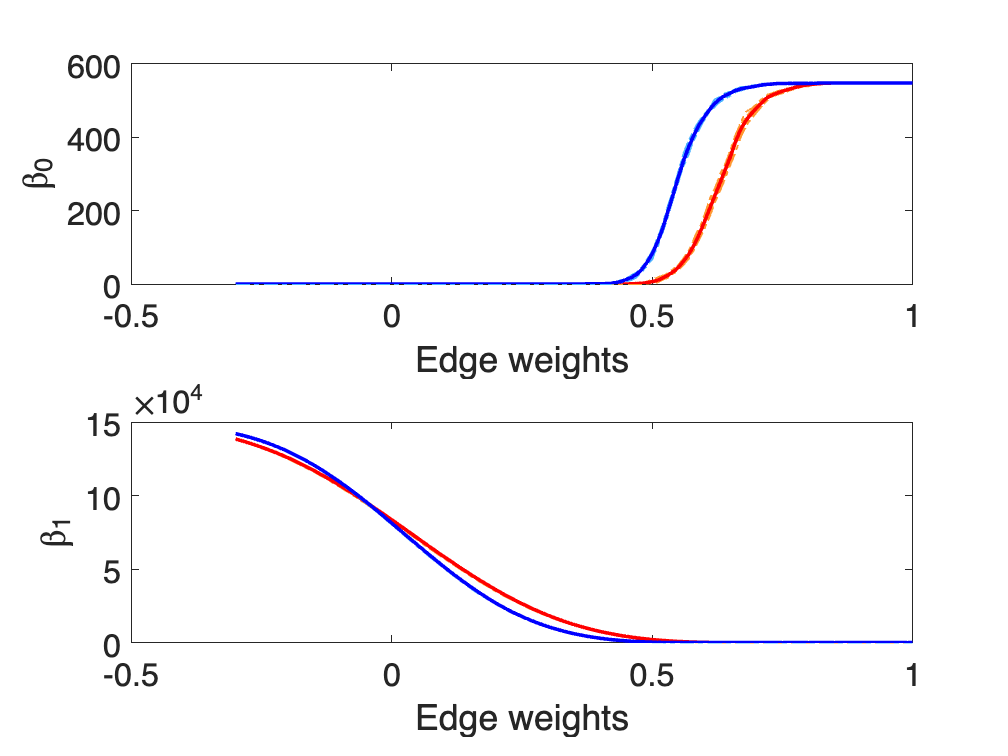

thresholds=[-0.3:0.01:1]; %you can change the range
PH_graph_betti_display(MSTpi, MSTco,thresholds)

### Topological inference on Jacobian determinant

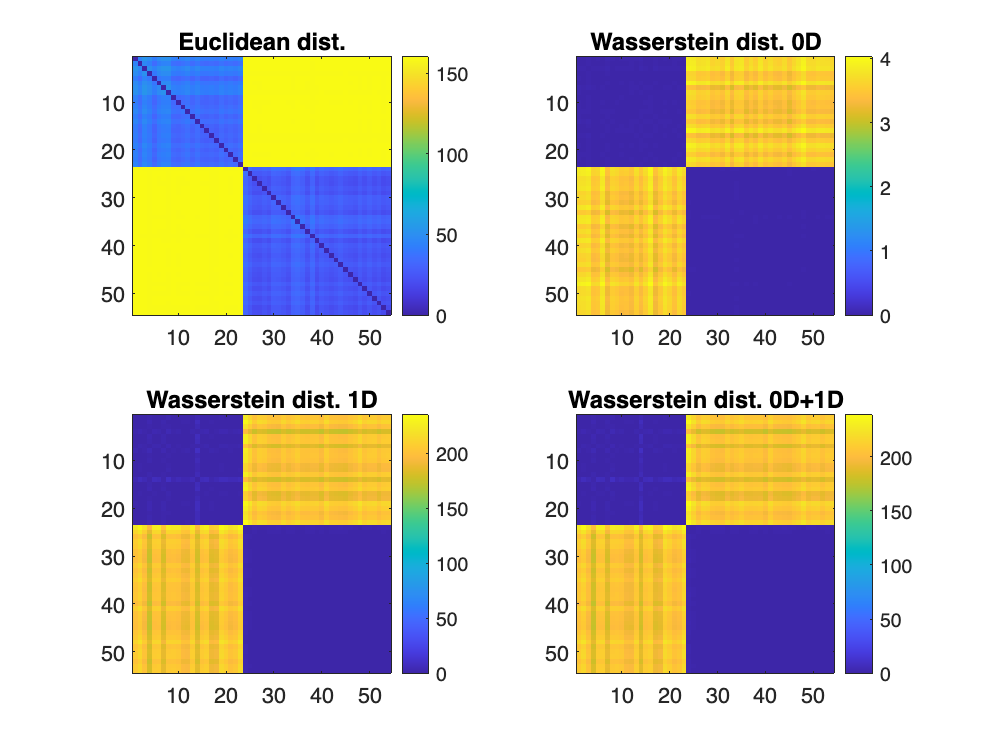

lossMtx = WS_pdist2(MSTpi,MSTco);
WS_pdist2_display(MSTpi,MSTco);

% p-value computation using the raio statistic (between-distance/within-distance)
%Here we show example of using the combined distance. For different
%distances,use lossMtx.D0 or lossMtx.D1, lossMtx.D01 = lossMtx.D0 + lossMtx.D1.

observed = WS_ratio(lossMtx.D0, nGroup_pi, nGroup_co) 

observed = 320.3088

nTrans = 1000000; %Total number of transpositions
permNo = 1000; %Total number of intermixed permutations. This is needed to introduce randomness.

[transStat, ~] = WS_transpositions(lossMtx.D0, nGroup_pi, nGroup_co, nTrans, permNo); 
transPval = online_pvalues(transStat', observed);
pval = transPval(end)

pval = 0

observed = WS_ratio(lossMtx.D1, nGroup_pi, nGroup_co)

observed = 341.1202

[transStat, ~] = WS_transpositions(lossMtx.D1, nGroup_pi, nGroup_co, nTrans, permNo); 
transPval = online_pvalues(transStat', observed);
pval = transPval(end)

pval = 0

observed = WS_ratio(lossMtx.D01, nGroup_pi, nGroup_co)

observed = 340.7356

[transStat, ~] = WS_transpositions(lossMtx.D01, nGroup_pi, nGroup_co, nTrans, permNo); 
transPval = online_pvalues(transStat', observed);
pval = transPval(end)

pval = 0

%figure; %hisgrom with 25 bins
%plot_distribution(transStat, 25, observed)

### Distributional properties of within- and between distances

%Distances are statitically indepdendent. 

%controls
m = 31; 
%maltreated
n =  23;

lossMtx = WS_pdist2(MSTco,MSTpi);

s=50;
dist0 = WS_distributions(lossMtx.D0, m, n);
[Z Zobserved pvalue] = stat_Z(dist0.between,dist0.within)

Z =    49.2054   48.9556   48.1893   48.8895   48.2931   48.3797   47.8264   49.0574   47.7168   47.0158   48.3209   47.9049   48.3964   47.8985   48.5532   47.9178   48.6817   48.3450   48.2538   48.0172   47.7319   48.3478   48.5702   49.0445   48.4440   47.8459   48.9398   49.1028   48.1918   48.0921   49.3624   48.9352   49.2441   48.7335   48.8370   48.3895   49.3896   48.2033   47.9682   48.2325   47.9693   49.1179   48.4818   49.1716   48.6403   49.1324   49.0320   48.4930   48.7186   47.8645


Zobserved = 503.7767

pvalue = 0

%testing normality of Z statistic through KS-test
[H, pValue] = kstest(Z)

H = logical
   1


pValue = 0

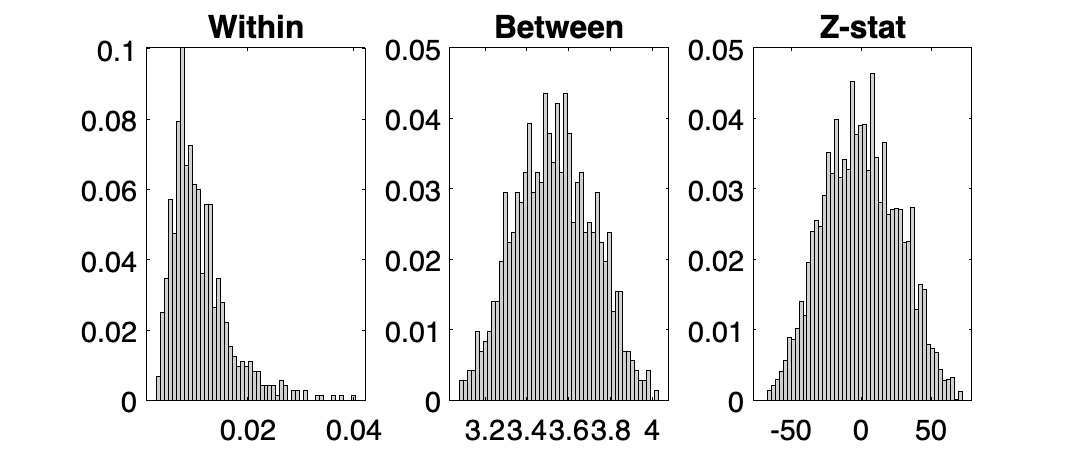

%0D distance

figure; subplot(1,3,1); plot_distribution(dist0.within, s, []); title('Within') 
subplot(1,3,2); plot_distribution(dist0.between, s, []); title('Between')
subplot(1,3,3); plot_distribution(Z, s, []); title('Z-stat')

%1D distance

dist1 = WS_distributions(lossMtx.D1, m, n);
[Z Zobserved pvalue] = stat_Z(dist1.between,dist1.within)

Z =    60.9805   55.5938   59.3822   59.4542   55.3053   55.0418   54.4277   58.3516   55.2742   56.1682   57.8794   57.3786   55.8590   54.3314   56.6364   55.2477   59.3121   55.9543   55.3130   54.9349   55.4998   56.5740   58.1752   60.1204   56.1376   56.8628   58.5763   56.3325   55.9265   57.1964   59.3156   61.4231   61.4729   59.1572   58.9638   58.5949   60.9183   59.1379   59.5850   60.6036   60.4183   59.4807   58.3680   59.9597   59.1493   61.3542   59.5496   59.1804   58.9156   59.2854


Zobserved = 500.2131

pvalue = 0

%testing normality of Z statistic through KS-test
[H, pValue] = kstest(Z)

H = logical
   1


pValue = 0

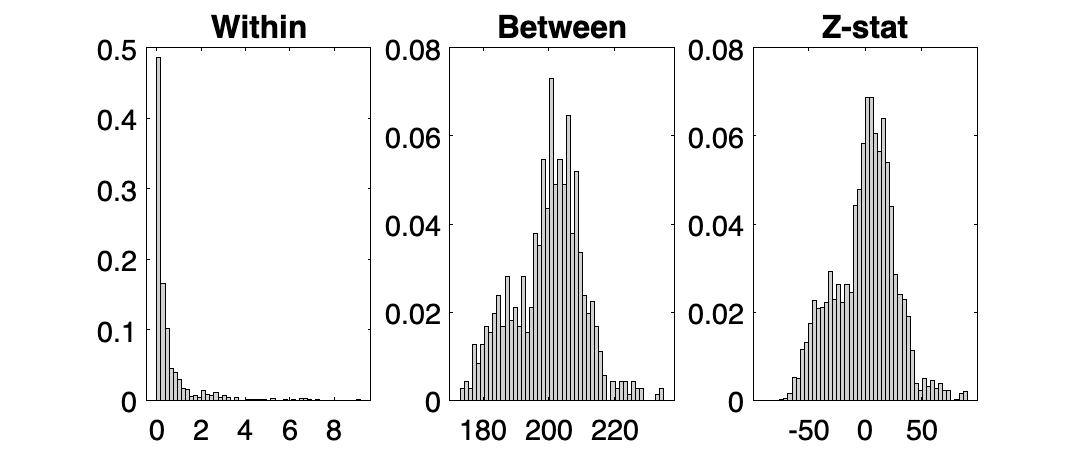


figure; subplot(1,3,1); plot_distribution(dist1.within, s, []); title('Within')  
subplot(1,3,2); plot_distribution(dist1.between, s, []);title('Between')
subplot(1,3,3); plot_distribution(Z, s, []); title('Z-stat') 

%0D + 1D combined distance

dist01 = WS_distributions(lossMtx.D01, m, n);
[Z Zobserved pvalue] = stat_Z(dist01.between,dist01.within)

Z =    61.1002   55.7740   59.5035   59.5867   55.4774   55.2186   54.6023   58.5004   55.4367   56.3078   58.0210   57.5190   56.0262   54.5084   56.7970   55.4140   59.4428   56.1195   55.4844   55.1067   55.6599   56.7318   58.3177   60.2477   56.3023   57.0084   58.7204   56.5064   56.0894   57.3423   59.4580   61.5328   61.5873   59.2906   59.1014   58.7291   61.0419   59.2624   59.7000   60.7110   60.5233   59.6170   58.5066   60.0911   59.2812   61.4682   59.6835   59.3094   59.0517   59.4022


Zobserved = 502.9315

pvalue = 0

%testing normality of Z statistic through KS-test
[H, pValue] = kstest(Z)

H = logical
   1


pValue = 0

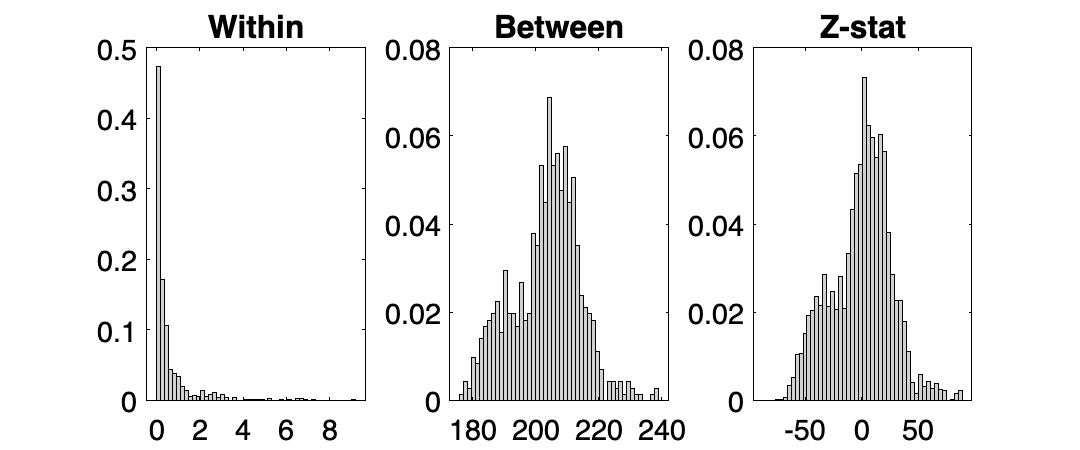


figure; subplot(1,3,1); plot_distribution(dist01.within, s, []); ; title('Within')   
subplot(1,3,2); plot_distribution(dist01.between, s, []); title('Between')
subplot(1,3,3); plot_distribution(Z, s, []); title('Z-stat') 